# Space Telecommunication Project - Root-Raised Cosine

Hugo LANCERY

Lucie MICHELET

Here is the second part of our work, the calculation for the Root-Raised Cosine pulse.

clear all
close all

## I[m] and Q[m] sequences

M=10 (Max number of index)

m={0, 1, …, M_(-1)} (Sequence index)

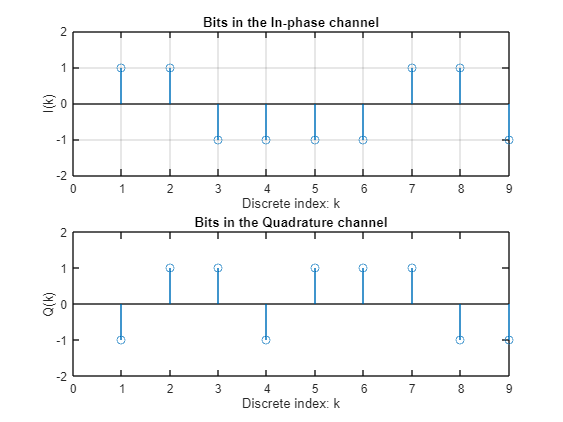

% Define the set of values
values = [1, -1];
M = 10;
% Generate random indices to select values from the set
indices_I = randi(length(values), 1, M); % Adjust 100 to the desired length of your signal
indices_Q = randi(length(values), 1, M); % Adjust 100 to the desired length of your signal

% Create the signals
I = values(indices_I);
Q = values(indices_Q);
A = complex(I,Q);

subplot(2, 1, 1);
stem(I)
ylim([-2 2])
xlim([0 M-1])
title('Bits in the In-phase channel');
xlabel('Discrete index: k');
ylabel('I(k)');
grid on;

subplot(2, 1, 2);
stem(Q);
ylim([-2 2])
xlim([0 M-1])
title('Bits in the Quadrature channel');
xlabel('Discrete index: k');
ylabel('Q(k)');

## The pulse p(t) time representation

Now we will compute the calculation with the Root-Raides Cosine pulse :

                                                        

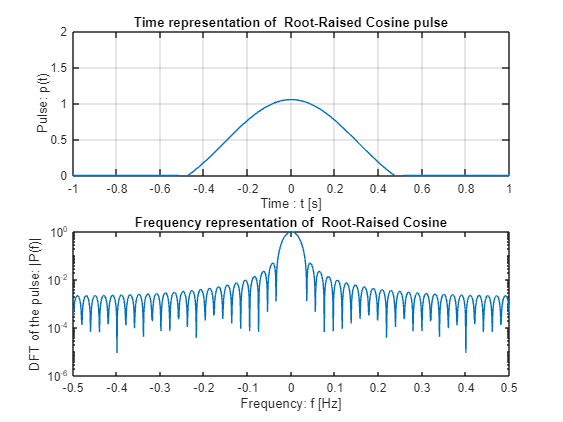

%% ---------------------- Root raised -------------------------------------
%Calculation of the Root-RaisedCosine pulse
Ac = 1;       % Amplitude
Ts = 1;     % Largeur du rectangle
N = 100;
t = linspace(-1, 1, N);
F0 = N/Ts;
np = 2^10;


%btw 0 and 1
alpha = 0.2; 

res = [];
for i = 1:length(t)
    if t(i)>Ts/2 || t(i)<-Ts/2 
        res = [res 0];
    else 
        res = [res (sin(2*pi*t(i)*(1-alpha)/Ts)+(8*alpha*t(i))/Ts*cos(2*pi*t(i)*(1+alpha)/Ts))/(2*pi*t(i)/Ts*(1-(8*alpha*t(i)/Ts)^2))];
    end
end

p_t = res;
pt = res;
p_t_2 = find(p_t ==0);

p_t_f = [];
for i = 26:75
    p_t_f = [p_t_f p_t(i)];
end

% time representation
fp= fftshift(fft(p_t,np));

frequencies_normalized = linspace(-0.5, 0.5, np);

% Tracer le signal pulse p(t)
subplot(2, 1, 1);
plot(t, p_t);
ylim([0 2]);
title('Time representation of  Root-Raised Cosine pulse');
xlabel('Time : t [s]');
ylabel('Pulse: p(t)');
grid on;

%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
semilogy(frequencies_normalized, abs(fp)/max(fp));
title('Frequency representation of  Root-Raised Cosine');
xlabel('Frequency: f [Hz]');
ylabel('DFT of the pulse: |P(f)|');

## In-phase information signal

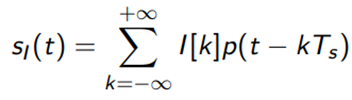

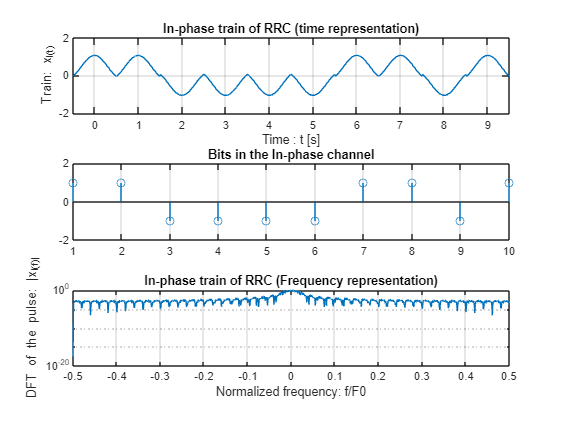

nb_1 = sum(p_t_f);
s_I = I(1,1)*p_t_f;

for i = 2:M
    p_t_rand_2_cat = I(1,i).*p_t_f;
    s_I = cat(2,s_I,p_t_rand_2_cat);
end

F0 = N/Ts;
Dt = Ts/N;

P_f_k_I = fftshift(fft(s_I, 2^10)); 

f = linspace(-0.5, 0.5, 2^10);

figure;
subplot(3, 1, 1);
plot(linspace(-0.5, 9.5, length(s_I)), s_I);
ylim([-2 2])
title('In-phase train of RRC (time representation)');
xlabel('Time : t [s]');
ylabel('Train: x_I(t)');
xlim([-0.5 9.5])
grid on;
subplot(3,1,2)
stem(I)
ylim([-2 2]);
title('Bits in the In-phase channel');
grid on;
%Tracer Frequency representation of the rect pulse
subplot(3, 1, 3);
semilogy(f, abs(P_f_k_I)/F0);
xlim([-0.5 0.5])
title('In-phase train of RRC (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_I(f)|');
grid on;

## Quadrature information signal

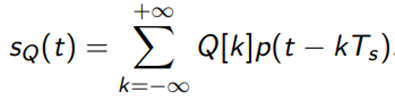

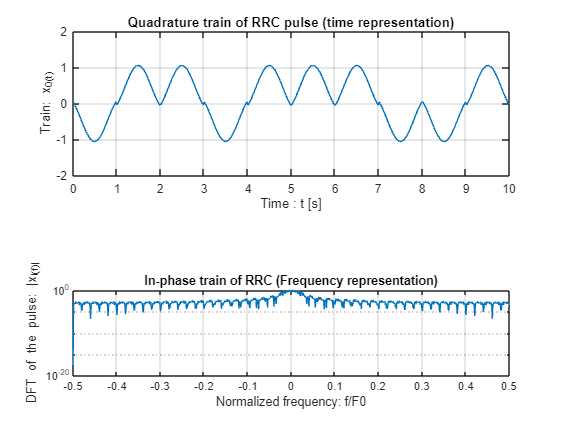

s_Q = Q(1,1)*p_t_f;

for i = 2:M
    p_t_rand_2_cat = Q(1,i)*p_t_f;
    s_Q = cat(2,s_Q,p_t_rand_2_cat);
end

F0 = N/Ts;
f = linspace(-0.5, 0.5, 2^10);
P_f_k_Q = fftshift(fft(s_Q, 2^10)); 

subplot(2, 1, 1);
plot(linspace(0, 10, length(s_Q)), s_Q);
ylim([-2 2])
title('Quadrature train of RRC pulse (time representation)');
xlabel('Time : t [s]');
ylabel('Train: x_Q(t)');
grid on;

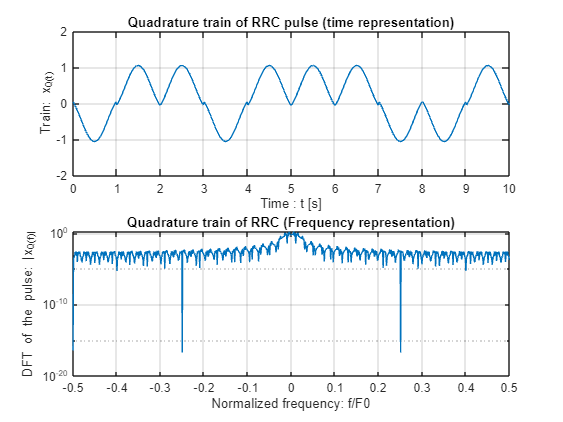


%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
semilogy(f, abs(P_f_k_Q)/F0);
xlim([-0.5 0.5])
title('Quadrature train of RRC (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_Q(f)|');
grid on;

## The transmitted signal

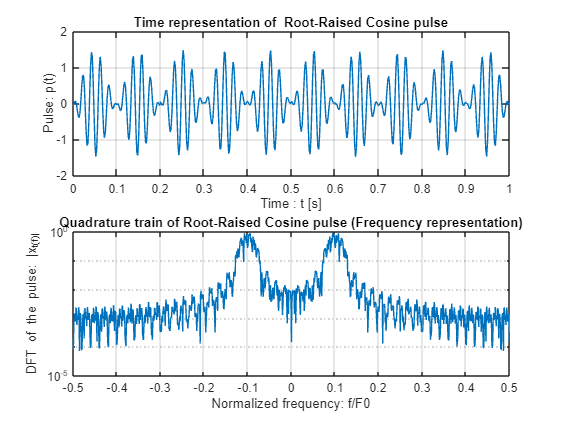

%% transmited signal 
F0 = N/Ts;
Dt = Ts/N;
fc = 5;
%t = linspace(-0.5,10,M*N/2);
t = linspace(0,10,5*N);
p_t = p_t_f;
%I
s_I = I(1,1)*p_t;

for i = 2:M
    p_t_rand_2_cat = I(1,i).*p_t;
    s_I = cat(2,s_I,p_t_rand_2_cat);
end


%Q
s_Q = Q(1,1)*p_t;

for i = 2:M
    p_t_rand_2_cat = Q(1,i)*p_t;
    s_Q = cat(2,s_Q,p_t_rand_2_cat);
end

%xt
x_t = s_I.*cos(2*pi*fc*t)-s_Q.*sin(2*pi*fc*t);

%freq
P_f_k_I = fftshift(fft(s_I, 2^10)); 
P_f_k_Q = fftshift(fft(s_Q, 2^10)); 
P_f_k_xt = fftshift(fft(x_t, 2^10)); 

f = linspace(-0.5, 0.5, 2^10);

% Tracer le signal rcc x(t)
subplot(2, 1, 1);
plot(linspace(0,1,length(x_t)), x_t);

title('Time representation of  Root-Raised Cosine pulse');
xlabel('Time : t [s]');
ylabel('Pulse: p(t)');
grid on;
%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
semilogy(f, abs(P_f_k_xt)/F0);
xlim([-0.5 0.5])
title('Quadrature train of Root-Raised Cosine pulse (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_t(f)|');
grid on;

## Adding random noise

We assume an ideal “distortionless” channel with gaussian random disturbance 

We get :   

We chose a sigma = 0.5 so the rest of the project stays pretty accurate and understandable. But we also run the code with higher values (ex : 4)  to see the differences that occurs. 

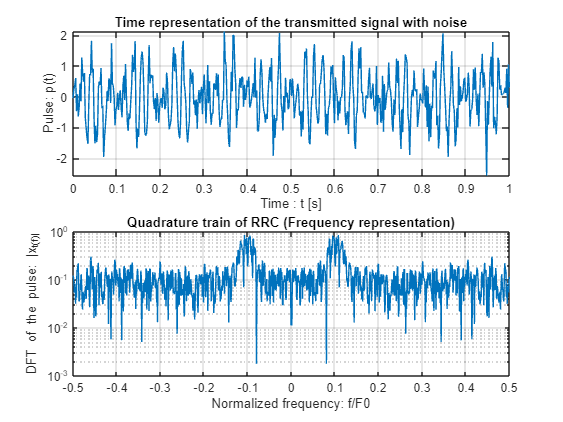

n = randn(1, length(x_t));
sign = 0.5;
x_rt = x_t+sign*n;

P_f_k_xrt = fftshift(fft(x_rt, 2^10)); 

subplot(2, 1, 1);
plot(linspace(0,1,length(x_rt)), x_rt);
title('Time representation of the transmitted signal with noise');
xlabel('Time : t [s]');
ylabel('Pulse: p(t)');
grid on;
%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
semilogy(f, abs(P_f_k_xrt)/F0);
xlim([-0.5 0.5])
title('Quadrature train of RRC (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_t(f)|');
grid on;

## Compare x_t and xr_t

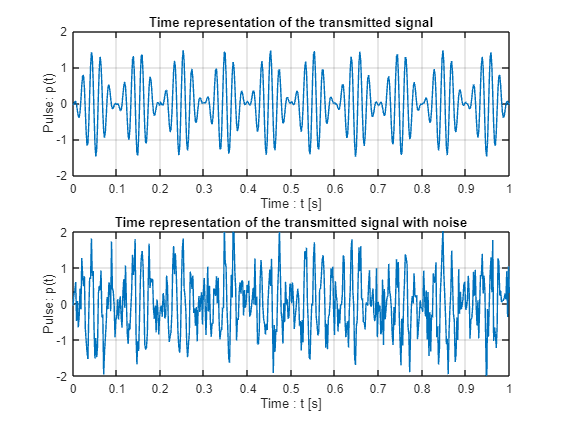

subplot(2, 1, 1);
plot(linspace(0,1,length(x_t)), x_t);
title('Time representation of the transmitted signal');
xlabel('Time : t [s]');
ylim([-2 2])
ylabel('Pulse: p(t)');
grid on;
%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
plot(linspace(0,1,length(x_rt)), x_rt);
title('Time representation of the transmitted signal with noise');
xlabel('Time : t [s]');
ylabel('Pulse: p(t)');
ylim([-2 2])
grid on;

## Demodulation

## sI

We can see on the first graph oursignal multiplied by cos (2πf_c t), followed by the second graph where we can clearly see the « useless » replicas

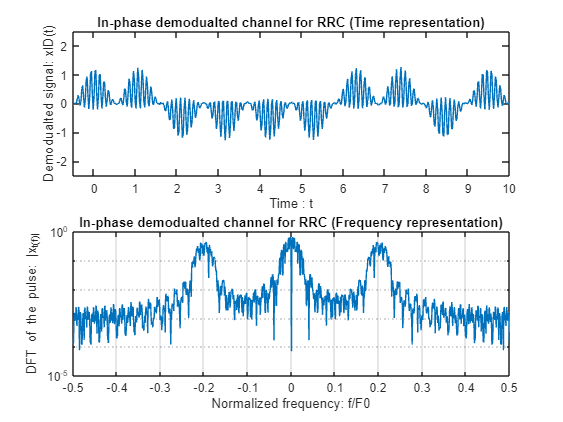

si = x_t.*cos(2*pi*fc*t);
P_f_i = fftshift(fft(si, 2^10)); 

subplot(2, 1, 1);
plot(linspace(-0.5,10,length(si)),si)
xlim([-0.5 10])
ylim([-2.5 2.5])
title('In-phase demodualted channel for RRC (Time representation)');
xlabel('Time : t');
ylabel('Demodualted signal: xID(t)');

%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
f = linspace(-0.5, 0.5, 2^10);
semilogy(f, abs(P_f_i)/F0);
title('In-phase demodualted channel for RRC (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_t(f)|');
grid on;

## sQ

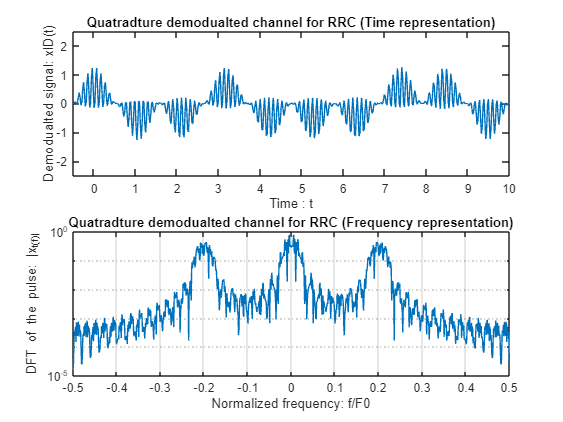

sq = x_t.*sin(2*pi*fc*t);
P_f_q = fftshift(fft(sq, 2^10)); 

subplot(2, 1, 1);
plot(linspace(-0.5,10,length(sq)),sq)
xlim([-0.5 10])
ylim([-2.5 2.5])
title('Quatradture demodualted channel for RRC (Time representation)');
xlabel('Time : t');
ylabel('Demodualted signal: xID(t)');

%Tracer Frequency representation of the rect pulse
subplot(2, 1, 2);
f = linspace(-0.5, 0.5, 2^10);
semilogy(f, abs(P_f_q)/F0);
title('Quatradture demodualted channel for RRC (Frequency representation)');
xlabel('Normalized frequency: f/F0');
ylabel('DFT of the pulse: |x_t(f)|');
grid on;

## Matched Filter : time 

After the demodulation, we need to apply the matched filter h_MF (t) to maximize the Signal-to-Noise Ratio.

With x_rI (t) = x_r(t)cos (2πf_c t), the demodulated signal.

The signal after the matched filter can be indicated as:

--> We had better results in RRC with the time method.

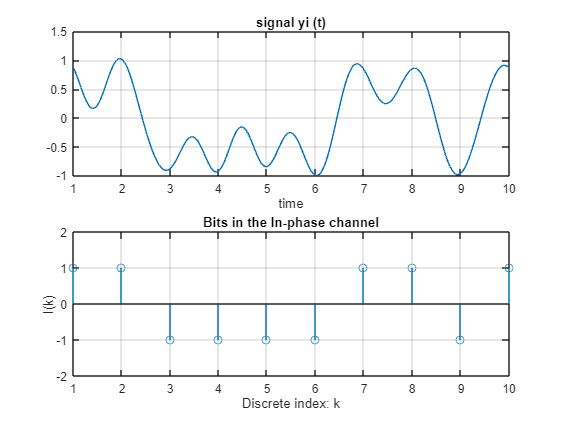

F=linspace(-0.5,0.5,2^10);
Bx=0.05;
H=rectpuls(F/Bx);
h=fftshift(ifft(fftshift(H)));
hmf=pt.*-1;

vi=conv(h,x_rt.*cos(2*pi*fc*t),'same');
yi=conv(vi,hmf,'same');

yi_n = [];
for i = 290:790
    yi_n = [yi_n yi(i)];
end


figure;
subplot(2,1,1)
plot(linspace(1,11,length(yi_n)),-real(yi_n)/max(real(yi_n)));
xlim([1 10])
xlabel('time');
title('signal yi (t)');
grid on;
subplot(2, 1, 2);
stem(I)
ylim([-2 2])
title('Bits in the In-phase channel');
xlabel('Discrete index: k');
ylabel('I(k)');
grid on;

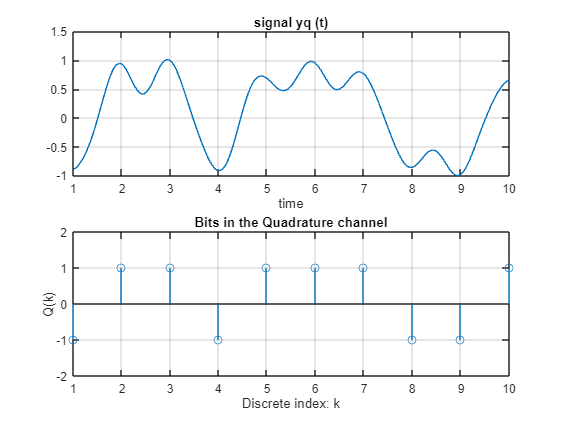

F=linspace(-0.5,0.5,2^10);
Bx=0.05;
H=rectpuls(F/Bx);
h=fftshift(ifft(fftshift(H)));
hmf=pt.*-1;

vq=conv(h,x_rt.*-sin(2*pi*fc*t),'same');
yq=conv(vq,hmf,'same');

yq_n = [];
for i = 290:790
    yq_n = [yq_n yq(i)];
end


figure;
subplot(2,1,1)
plot(linspace(1,11,length(yq_n)),-real(yq_n)/max(real(yq_n)));
xlim([1 10])
title('signal yq (t)');
xlabel('time');
grid on;
subplot(2, 1, 2);
stem(Q)
ylim([-2 2])
title('Bits in the Quadrature channel');
xlabel('Discrete index: k');
ylabel('Q(k)');
grid on;

## Matched filter : frequence

We can do the same but with the frequential domain.

The signal after the matched filter can be indicated as:

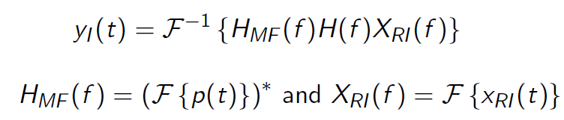

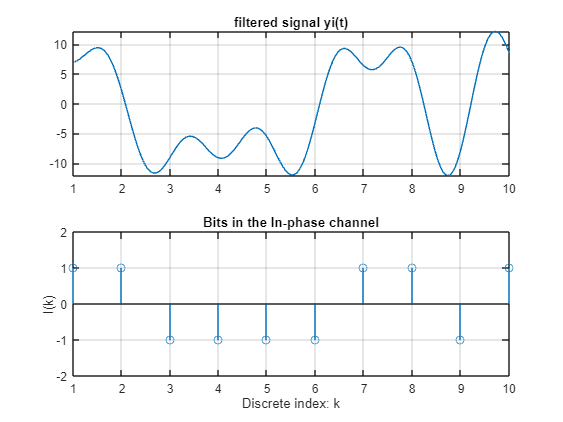

fx_rit = fftshift(fft(x_rt.*cos(2*pi*fc*t),2^10));
Bx=0.03;
h = rectpuls(F/Bx);

fhmf = fftshift(conj(fft(pt,2^10)));

figure;
subplot(2, 1, 1);
fyI = ifft(fftshift(fhmf.*h.*fx_rit));
plot(linspace(1,22,length(fyI)),real(fyI)) 
xlim([1 10])
title('filtered signal yi(t)');
grid on;
subplot(2, 1, 2);
stem(I)
ylim([-2 2])
title('Bits in the In-phase channel');
xlabel('Discrete index: k');
ylabel('I(k)');
grid on;

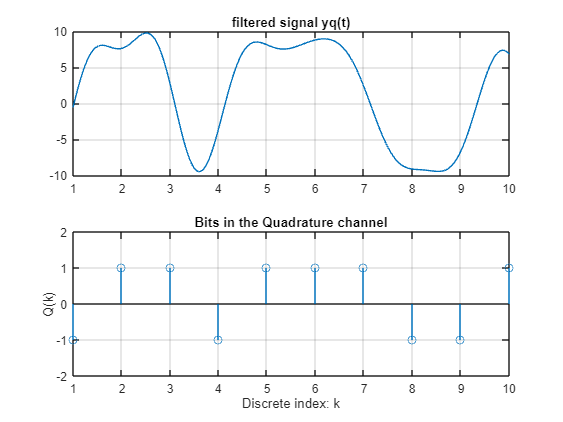

fx_rqt = fftshift(fft(x_rt.*-sin(2*pi*fc*t),2^10));
Bx=0.03;
h = rectpuls(F/Bx);

fhmf = fftshift(conj(fft(pt,2^10)));

figure;
subplot(2, 1, 1);
fyQ = ifft(fftshift(fhmf.*h.*fx_rqt));
plot(linspace(1,22,length(fyQ)),real(fyQ)) 
xlim([1 10])
title('filtered signal yq(t)');
grid on;
subplot(2, 1, 2);
stem(Q)
ylim([-2 2])
title('Bits in the Quadrature channel');
xlabel('Discrete index: k');
ylabel('Q(k)');
grid on;

## Plot xi_r(t) on frequence, h(t) and hmf(t)

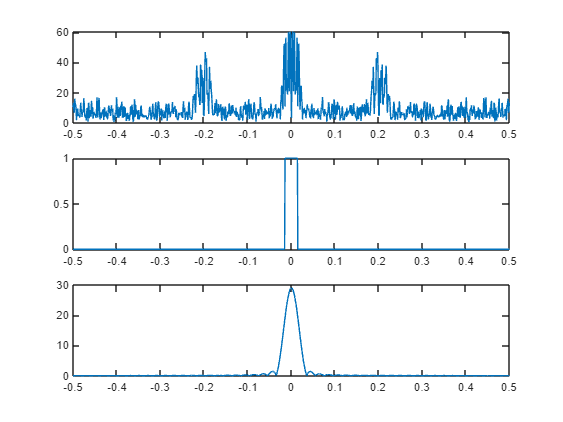

figure;
subplot(3,1,1)
plot(F,abs(fx_rit))
subplot(3,1,2)
plot(F,h)
subplot(3,1,3)
plot(F,abs(fhmf))

## Sampling and sequence reconstruction

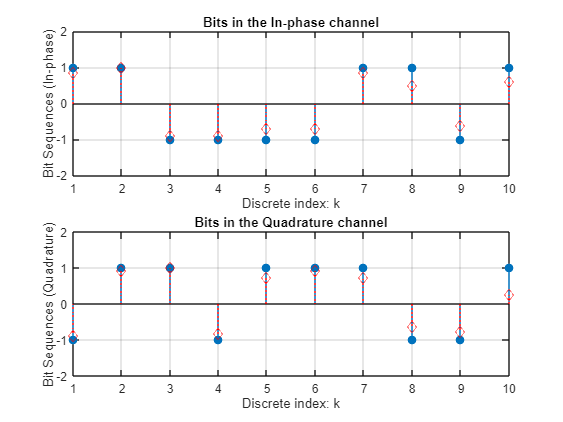

%normalize
minVal = min(yi_n);
maxVal = max(yi_n);
y_i_m = (yi_n) / ( -abs(maxVal - minVal) );
y_i_m_c = y_i_m([1:length(y_i_m)*0.88]);
y_r_v_i = y_i_m_c(1:fix(length(y_i_m_c)/9):length(y_i_m_c));
figure;
subplot(2,1,1)
stem(I,"filled");
ylim([-2 2]);
title("Bits in the In-phase channel");
xlabel("Discrete index: k")
ylabel("Bit Sequences (In-phase)")
hold on;
grid on;
stem(real(y_r_v_i),":diamondr");


minVal = min(yq_n);
maxVal = max(yq_n);
y_q_m = (yq_n) / ( -abs(maxVal - minVal) );
y_q_m_c = y_q_m([1:length(y_i_m)*0.88]);
y_r_v_q = y_q_m_c(1:fix(length(y_q_m_c)/9):length(y_q_m_c));
subplot(2,1,2)
stem(Q,"filled");
ylim([-2 2]);
title("Bits in the Quadrature channel");
xlabel("Discrete index: k")
ylabel("Bit Sequences (Quadrature)")
hold on;
grid on;
stem(real(y_r_v_q),":diamondr");

We have accurate results, with small differences on amplitude. But, once we increase the noise, the results get worse. The max and min values are bot always accurate and the amplitude is highly modified.

## Conclusion

 We conclude that the noise has a huge impact on the demodulated signal. The lower the noise is, the more accurate will be the demodulated signal. 